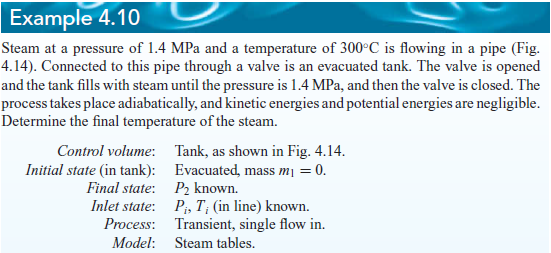

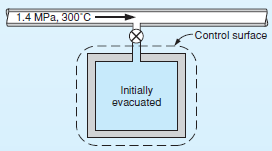

# transient process

% unknowns
u = symunit;
syms mi m2 u2 positive;
% inflow state
pi = 1.4*u.MPa;
Ti = 300*u.Celsius;
hi = 3040.35*u.kJ/u.kg; % superheated vapor water
% exit state
me = 0;
he = 0;
% pipe state 1
m1 = 0;
u1 = 0;
% pipe state 2
p2 = 1.4*u.MPa;
% conservation of mass
mi = m2;
% energy equation
eqn = simplify(m2*u2-m1*u1 == mi*hi-me*he);
u2 = rhs(eqn);
T2 = interp1([2952.50 3121.10], [400 500], double(removeUnits(u2)))*u.Celsius;
T2_vpa = vpa(T2, 5) %#ok

$$T2\_vpa = 452.11\,\mathrm{{}^{\circ}C}$$

clear T2_vpa;
clearassum;